# radial profiles of HI and H2

## load important things

snap=99;
[subs,fofs,subsInfo]=illustris.loadFofSub(snap);

massThresh=1e9;
satMask=illustris.infrastructure.generateMask('subs',subs','fofs',fofs,'mass',massThresh,'snap',snap,'sats');

## load HI H2 values by components

load('C:\Users\eladz\Documents\workProjects\matlab_scripts\IllustrisTNG\matFiles\hih2Catalog_snp99_TNG100.mat')


## build stellar mass - HI mass relationship

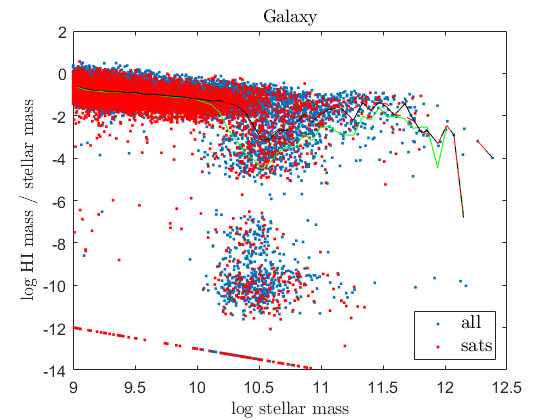


mmask=hih2Struct.galMask & hih2Struct.Gal.GalHIMass(1,:)>0;
galH_star=mk_meanMedian_bin(log10(hih2Struct.galMass(mmask)),...
    log10(hih2Struct.Gal.GalHIMass(1,mmask)./hih2Struct.galMass(mmask)),'nb',50);

mmask=hih2Struct.galMask & hih2Struct.Gal.GalHIMass(1,:)>0 & subsInfo.isCentral;
galH_starC=mk_meanMedian_bin(log10(hih2Struct.galMass(mmask)),...
    log10(hih2Struct.Gal.GalHIMass(1,mmask)./hih2Struct.galMass(mmask)),'nb',50);

figure
smass=hih2Struct.galMass(hih2Struct.galMask);
hMass=hih2Struct.Gal.GalHIMass(1,hih2Struct.galMask);
hMass(hMass==0)=1e-3;
h(1)=plot(log10(smass),log10(hMass./smass),'.','DisplayName','all');
hold on;

smass=hih2Struct.galMass(hih2Struct.galMask & satMask);
hMass=hih2Struct.Gal.GalHIMass(1,hih2Struct.galMask &satMask);
hMass(hMass==0)=1e-3;
h(2)=plot(log10(smass),log10(hMass./smass),'.r','DisplayName','sats');



plot(galH_star.xMean,galH_star.yMean,'g')
plot(galH_star.xMedian,galH_star.yMedian,'k')
plot(galH_starC.xMedian,galH_starC.yMedian,'r--')
legend(h,'Interpreter',"latex",'FontSize',14,'Location','southeast')

xlabelmine('log stellar mass');
ylabelmine(' log HI mass / stellar mass');
titlemine('Galaxy');
set(gca,'fontsize',12)

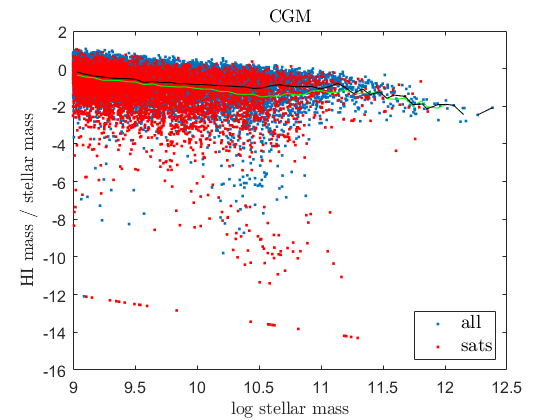




mmask=hih2Struct.galMask & hih2Struct.CGMall.CGMallHIMass(1,:)>0;
cgmH_star=mk_meanMedian_bin(log10(hih2Struct.galMass(mmask)),...
    log10(hih2Struct.CGMall.CGMallHIMass(1,mmask)./hih2Struct.galMass(mmask)),'nb',50);

figure
smass=hih2Struct.galMass(hih2Struct.galMask);
hMass=hih2Struct.CGMall.CGMallHIMass(1,hih2Struct.galMask);
hMass(hMass==0)=1e-3;
h(1)=plot(log10(smass),log10(hMass./smass),'.','DisplayName','all');
hold on;
smass=hih2Struct.galMass(hih2Struct.galMask & satMask);
hMass=hih2Struct.CGMall.CGMallHIMass(1,hih2Struct.galMask & satMask);
hMass(hMass==0)=1e-3;
h(2)=plot(log10(smass),log10(hMass./smass),'.r','DisplayName','sats');

plot(cgmH_star.xMean,cgmH_star.yMean,'g')
plot(cgmH_star.xMedian,cgmH_star.yMedian,'k')

legend(h,'Interpreter',"latex",'FontSize',14,'Location','southeast')
xlabelmine('log stellar mass');
ylabelmine('HI mass / stellar mass');
titlemine('CGM');
set(gca,'fontsize',12)

## build H2 vs. stellar mass relationship

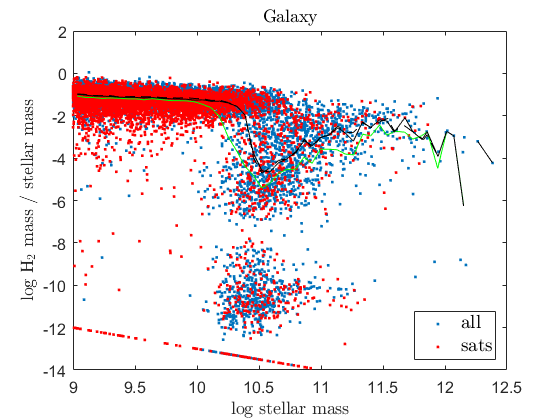

mmask=hih2Struct.galMask & hih2Struct.Gal.GalH2Mass(1,:)>0;
galH_star=mk_meanMedian_bin(log10(hih2Struct.galMass(mmask)),...
    log10(hih2Struct.Gal.GalH2Mass(1,mmask)./hih2Struct.galMass(mmask)),'nb',50);

mmask=hih2Struct.galMask & hih2Struct.Gal.GalHIMass(1,:)>0 & subsInfo.isCentral;
galH_starC=mk_meanMedian_bin(log10(hih2Struct.galMass(mmask)),...
    log10(hih2Struct.Gal.GalH2Mass(1,mmask)./hih2Struct.galMass(mmask)),'nb',50);

figure
smass=hih2Struct.galMass(hih2Struct.galMask);
hMass=hih2Struct.Gal.GalH2Mass(1,hih2Struct.galMask);
hMass(hMass==0)=1e-3;
h(1)=plot(log10(smass),log10(hMass./smass),'.','DisplayName','all');
hold on;
smass=hih2Struct.galMass(hih2Struct.galMask & satMask);
hMass=hih2Struct.Gal.GalH2Mass(1,hih2Struct.galMask & satMask);
hMass(hMass==0)=1e-3;
h(2)=plot(log10(smass),log10(hMass./smass),'.r','DisplayName','sats');

plot(galH_star.xMean,galH_star.yMean,'g')
plot(galH_star.xMedian,galH_star.yMedian,'k')
plot(galH_starC.xMedian,galH_starC.yMedian,'k--')
legend(h,'Interpreter',"latex",'FontSize',14,'Location','southeast')
xlabelmine('log stellar mass');
ylabelmine(' log $\mathrm{H_2}$ mass / stellar mass');
titlemine('Galaxy');
set(gca,'fontsize',12)

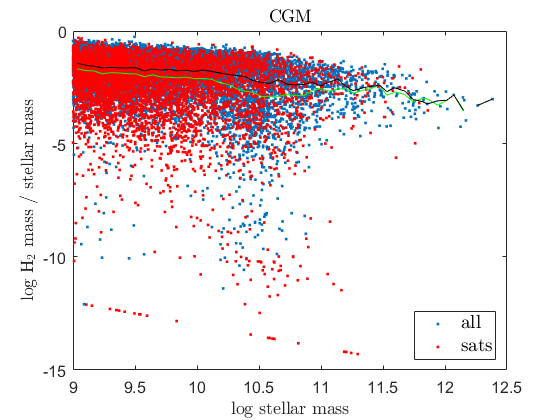



mmask=hih2Struct.galMask & hih2Struct.CGMall.CGMallH2Mass(1,:)>0;
cgmH_star=mk_meanMedian_bin(log10(hih2Struct.galMass(mmask)),...
    log10(hih2Struct.CGMall.CGMallH2Mass(1,mmask)./hih2Struct.galMass(mmask)),'nb',50);

figure
smass=hih2Struct.galMass(hih2Struct.galMask);
hMass=hih2Struct.CGMall.CGMallH2Mass(1,hih2Struct.galMask);
hMass(hMass==0)=1e-3;
h(1)=plot(log10(smass),log10(hMass./smass),'.','DisplayName','all');
hold on;
smass=hih2Struct.galMass(hih2Struct.galMask & satMask);
hMass=hih2Struct.CGMall.CGMallH2Mass(1,hih2Struct.galMask & satMask);
hMass(hMass==0)=1e-3;
h(2)=plot(log10(smass),log10(hMass./smass),'.r','DisplayName','sats');

plot(cgmH_star.xMean,cgmH_star.yMean,'g')
plot(cgmH_star.xMedian,cgmH_star.yMedian,'k')
legend(h,'Interpreter',"latex",'FontSize',14,'Location','southeast');
xlabelmine('log stellar mass');
ylabelmine('log $\mathrm{H_2}$ mass / stellar mass');
titlemine('CGM');
set(gca,'fontsize',12)

## perliminaries


colors=brewermap(8,'Set1');
cind=[2 5 3 1];
htag={'11-12','12-13','13-14','14-15'};
mtag={'9-10','10-11','11-12'};
modelTag=hih2Struct.Gal.Hmodel;

## arrange profiles

hprofs=generate_hih2_profiles_3d(hih2Struct,fofs,subs,'mask',satMask,'mean200','bins',0.1:0.3:2.2);

## plot by HI host mass

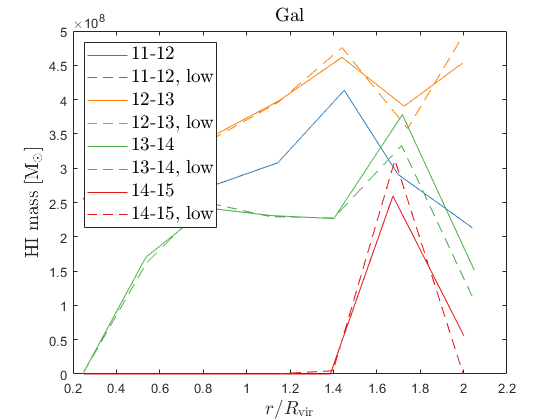


figure
h=[];

for j=1:4
    h(end+1)=plot(hprofs.byHost.xMed(:,j),hprofs.byHost.Gal.hiMassMed(1,:,j),'-',...
        'color',colors(cind(j),:),'DisplayName',htag{j});
    if j==1;hold on;end
    h(end+1)=plot(hprofs.byHostStar2(1).xMed(:,j),hprofs.byHostStar2(1).Gal.hiMassMed(1,:,j),'--',...
        'color',colors(cind(j),:),'DisplayName',[htag{j} ', low']);
%     h(end+1)=plot(hprofs.byHostStar2(2).xMed(:,j),hprofs.byHostStar2(2).Gal.hiMassMed(1,:,j),':',...
%         'color',colors(cind(j),:),'DisplayName',[htag{j} ', high']);
%     
end

legend(h,'fontsize',14,'location','northwest','interpreter','latex');
xlabelmine('$r/R_\mathrm{vir}$');
ylabelmine('HI mass $[\mathrm{M_\odot}]$');
titlemine('Gal');

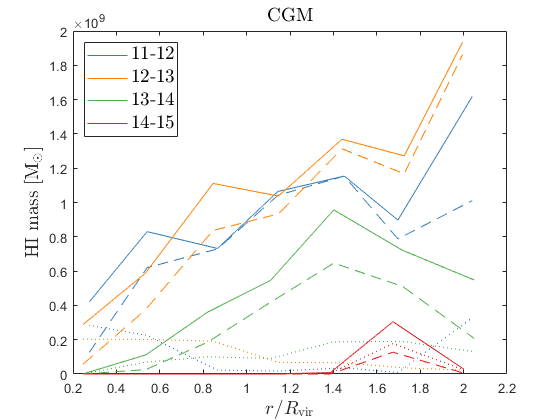


figure
h=[];

for j=1:4
    h(end+1)=plot(hprofs.byHost.xMed(:,j),hprofs.byHost.CGMall.hiMassMed(1,:,j),...
        'color',colors(cind(j),:),'DisplayName',htag{j});
    if j==1;hold on;end
    
    h(end+1)=plot(hprofs.byHost.xMed(:,j),hprofs.byHost.CGMin.hiMassMed(1,:,j),'--',...
        'color',colors(cind(j),:),'DisplayName',htag{j});
    
    h(end+1)=plot(hprofs.byHost.xMed(:,j),hprofs.byHost.CGMout.hiMassMed(1,:,j),':',...
        'color',colors(cind(j),:),'DisplayName',htag{j});
    
    
end

legend(h(1:3:12),'fontsize',14,'location','northwest','interpreter','latex');
xlabelmine('$r/R_\mathrm{vir}$');
ylabelmine('HI mass $[\mathrm{M_\odot}]$');
titlemine('CGM');

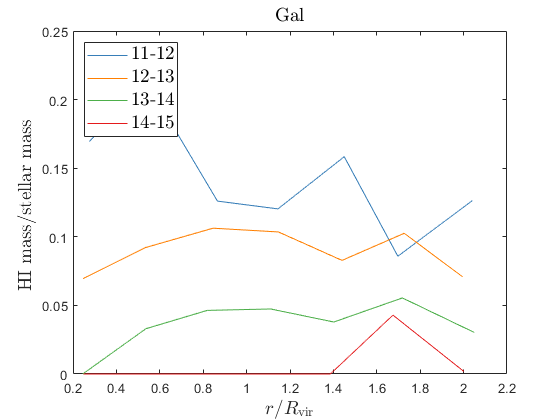


% normalized

figure
h=[];

for j=1:4
    h(end+1)=plot(hprofs.byHost.xMed(:,j),hprofs.byHost.Gal.hiMassMedN(1,:,j),...
        'color',colors(cind(j),:),'DisplayName',htag{j});
    if j==1;hold on;end
end

legend(h,'fontsize',14,'location','northwest','interpreter','latex');
xlabelmine('$r/R_\mathrm{vir}$');
ylabelmine('HI mass/stellar mass ');
titlemine('Gal');

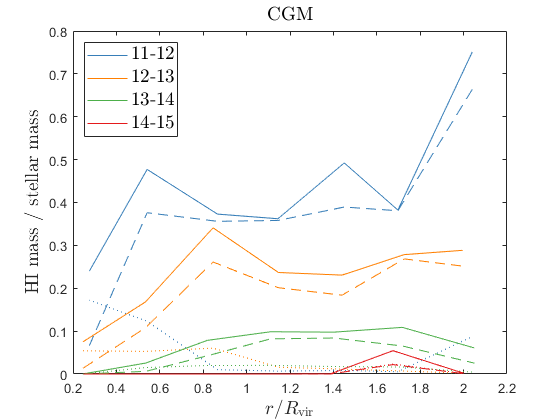


figure
h=[];

for j=1:4
    h(end+1)=plot(hprofs.byHost.xMed(:,j),hprofs.byHost.CGMall.hiMassMedN(1,:,j),...
        'color',colors(cind(j),:),'DisplayName',htag{j});
    if j==1;hold on;end
    
    h(end+1)=plot(hprofs.byHost.xMed(:,j),hprofs.byHost.CGMin.hiMassMedN(1,:,j),'--',...
        'color',colors(cind(j),:),'DisplayName',htag{j});
    
    h(end+1)=plot(hprofs.byHost.xMed(:,j),hprofs.byHost.CGMout.hiMassMedN(1,:,j),':',...
        'color',colors(cind(j),:),'DisplayName',htag{j});
    
    
end

legend(h(1:3:12),'fontsize',14,'location','northwest','interpreter','latex');
xlabelmine('$r/R_\mathrm{vir}$');
ylabelmine('HI mass / stellar mass');
titlemine('CGM');

## plot h2 mass

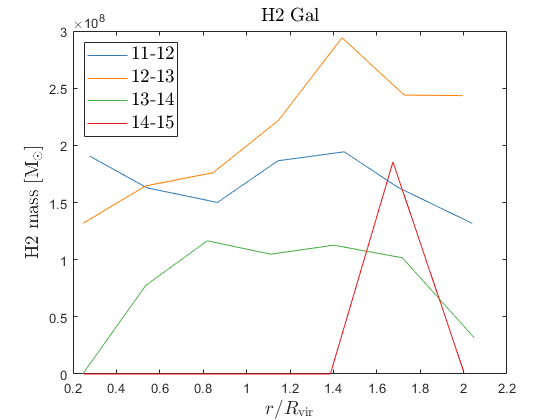



figure
h=[];

for j=1:4
    h(end+1)=plot(hprofs.byHost.xMed(:,j),hprofs.byHost.Gal.h2MassMed(1,:,j),...
        'color',colors(cind(j),:),'DisplayName',htag{j});
    if j==1;hold on;end
end

legend(h,'fontsize',14,'location','northwest','interpreter','latex');
xlabelmine('$r/R_\mathrm{vir}$');
ylabelmine('H2 mass $[\mathrm{M_\odot}]$');
titlemine('H2 Gal');

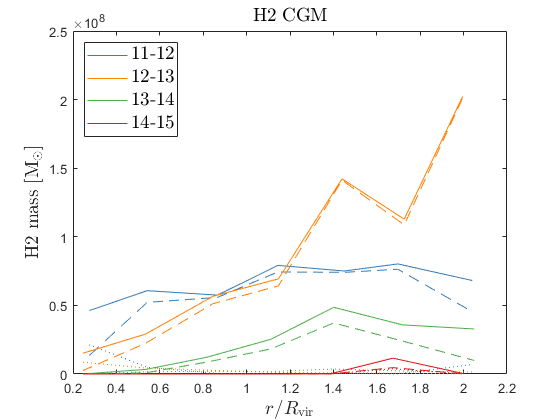


figure
h=[];

for j=1:4
    h(end+1)=plot(hprofs.byHost.xMed(:,j),hprofs.byHost.CGMall.h2MassMed(1,:,j),...
        'color',colors(cind(j),:),'DisplayName',htag{j});
    if j==1;hold on;end
    
    h(end+1)=plot(hprofs.byHost.xMed(:,j),hprofs.byHost.CGMin.h2MassMed(1,:,j),'--',...
        'color',colors(cind(j),:),'DisplayName',htag{j});
    
    h(end+1)=plot(hprofs.byHost.xMed(:,j),hprofs.byHost.CGMout.h2MassMed(1,:,j),':',...
        'color',colors(cind(j),:),'DisplayName',htag{j});
    
    
end

legend(h(1:3:12),'fontsize',14,'location','northwest','interpreter','latex');
xlabelmine('$r/R_\mathrm{vir}$');
ylabelmine('H2 mass $[\mathrm{M_\odot}]$');
titlemine(' H2 CGM');

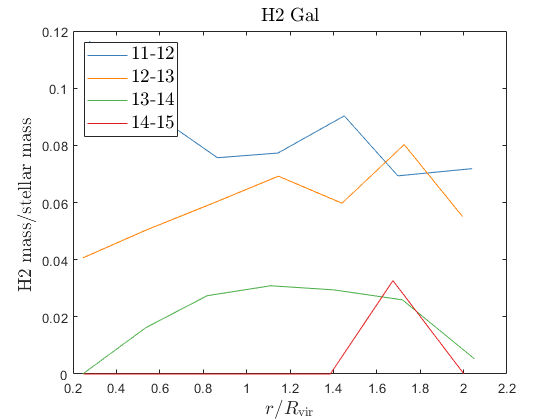


% normalized

figure
h=[];

for j=1:4
    h(end+1)=plot(hprofs.byHost.xMed(:,j),hprofs.byHost.Gal.h2MassMedN(1,:,j),...
        'color',colors(cind(j),:),'DisplayName',htag{j});
    if j==1;hold on;end
end

legend(h,'fontsize',14,'location','northwest','interpreter','latex');
xlabelmine('$r/R_\mathrm{vir}$');
ylabelmine('H2 mass/stellar mass ');
titlemine('H2 Gal');

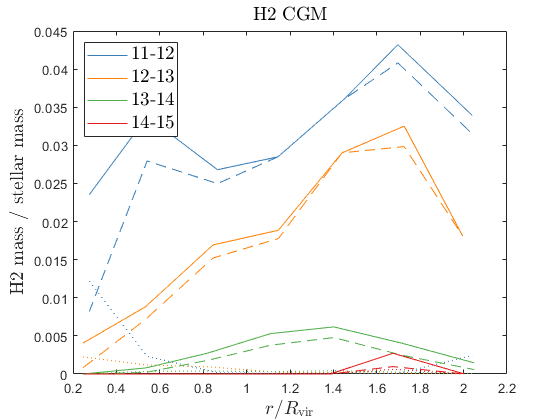


figure
h=[];

for j=1:4
    h(end+1)=plot(hprofs.byHost.xMed(:,j),hprofs.byHost.CGMall.h2MassMedN(1,:,j),...
        'color',colors(cind(j),:),'DisplayName',htag{j});
    if j==1;hold on;end
    
    h(end+1)=plot(hprofs.byHost.xMed(:,j),hprofs.byHost.CGMin.h2MassMedN(1,:,j),'--',...
        'color',colors(cind(j),:),'DisplayName',htag{j});
    
    h(end+1)=plot(hprofs.byHost.xMed(:,j),hprofs.byHost.CGMout.h2MassMedN(1,:,j),':',...
        'color',colors(cind(j),:),'DisplayName',htag{j});
    
    
end

legend(h(1:3:12),'fontsize',14,'location','northwest','interpreter','latex');
xlabelmine('$r/R_\mathrm{vir}$');
ylabelmine('H2 mass / stellar mass');
titlemine(' H2 CGM');

## plot offset by host

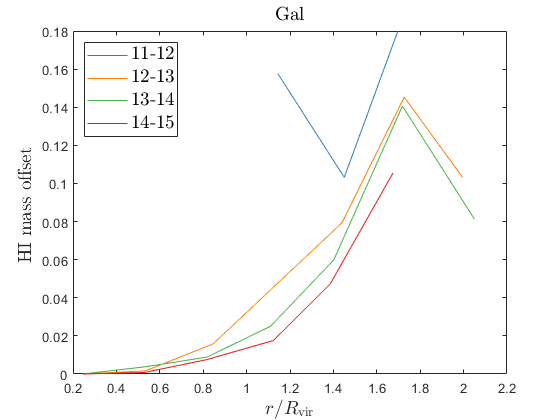


figure
h=[];

for j=1:4
    h(end+1)=plot(hprofs.byHost.xMed(:,j),hprofs.byHost.Gal.hiMassSFRMedN(1,:,j),...
        'color',colors(cind(j),:),'DisplayName',htag{j});
    if j==1;hold on;end
    % h(end+1)=plot(hprofs.byHost.xAvg(:,j),hprofs.byHost.Gal.hiMassAvgDN(1,:,j),'--',...
    %     'color',colors(cind(j),:),'DisplayName',htag{j});
end

legend(h,'fontsize',14,'location','northwest','interpreter','latex');
xlabelmine('$r/R_\mathrm{vir}$');
ylabelmine('HI mass offset ');
titlemine('Gal');

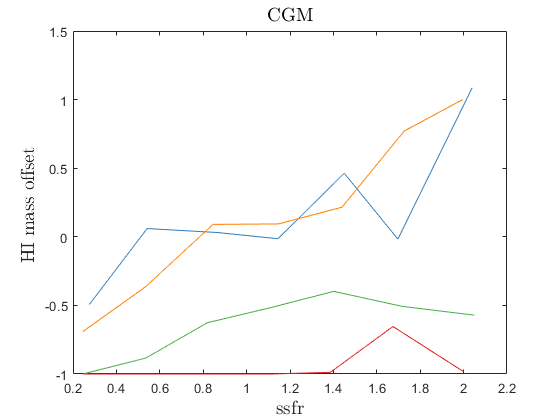


figure
h=[];

for j=1:4
    h(end+1)=plot(hprofs.byHost.xMed(:,j),hprofs.byHost.CGMall.hiMassMedDN(1,:,j),...
        'color',colors(cind(j),:),'DisplayName',htag{j});
    if j==1;hold on;end
    % h(end+1)=plot(hprofs.byHost.xAvg(:,j),hprofs.byHost.CGMall.hiMassAvgDN(1,:,j),'--',...
    %     'color',colors(cind(j),:),'DisplayName',htag{j});
    
    % h(end+1)=plot(hprofs.byHost.xMed(:,j),hprofs.byHost.CGMin.hiMassMed(1,:,j),'--',...
    %     'color',colors(cind(j),:),'DisplayName',htag{j});
    %
    % h(end+1)=plot(hprofs.byHost.xMed(:,j),hprofs.byHost.CGMout.hiMassMed(1,:,j),':',...
    %     'color',colors(cind(j),:),'DisplayName',htag{j});
    
    
end
xlabelmine('$r/R_\mathrm{vir}$');
ylabelmine('HI mass offset ');
titlemine('CGM');

## plot by host mass vs ssfr

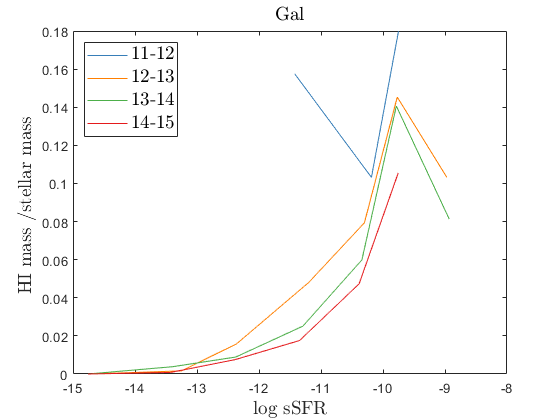

figure
h=[];

for j=1:4
    h(end+1)=plot(hprofs.byHost.xsfrMed(:,j),hprofs.byHost.Gal.hiMassSFRMedN(1,:,j),...
        'color',colors(cind(j),:),'DisplayName',htag{j});
    if j==1;hold on;end
    % h(end+1)=plot(hprofs.byHost.xAvg(:,j),hprofs.byHost.Gal.hiMassAvgDN(1,:,j),'--',...
    %     'color',colors(cind(j),:),'DisplayName',htag{j});
end

legend(h,'fontsize',14,'location','northwest','interpreter','latex');
xlabelmine('log sSFR');
ylabelmine('HI mass /stellar mass ');
titlemine('Gal');

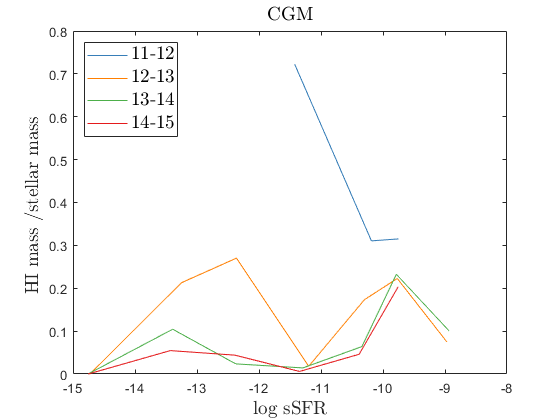


h=[];
figure
for j=1:4
    h(end+1)=plot(hprofs.byHost.xsfrMed(:,j),hprofs.byHost.CGMall.hiMassSFRMedN(1,:,j),...
        'color',colors(cind(j),:),'DisplayName',htag{j});
    if j==1;hold on;end
    % h(end+1)=plot(hprofs.byHost.xAvg(:,j),hprofs.byHost.Gal.hiMassAvgDN(1,:,j),'--',...
    %     'color',colors(cind(j),:),'DisplayName',htag{j});
end

legend(h,'fontsize',14,'location','northwest','interpreter','latex');
xlabelmine('log sSFR');
ylabelmine('HI mass /stellar mass ');
titlemine('CGM');

## plot H2 by host mass vs. SSFR

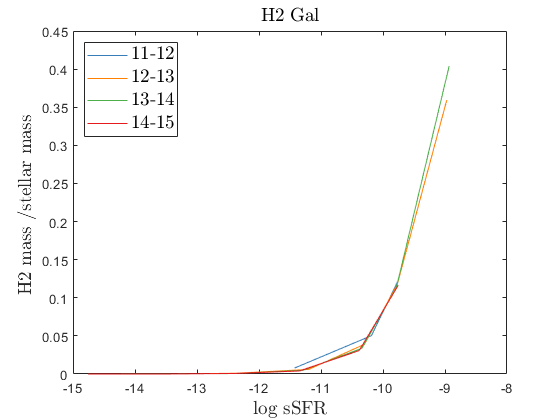

figure
h=[];

for j=1:4
    h(end+1)=plot(hprofs.byHost.xsfrMed(:,j),hprofs.byHost.Gal.h2MassSFRMedN(1,:,j),...
        'color',colors(cind(j),:),'DisplayName',htag{j});
    if j==1;hold on;end
    % h(end+1)=plot(hprofs.byHost.xAvg(:,j),hprofs.byHost.Gal.hiMassAvgDN(1,:,j),'--',...
    %     'color',colors(cind(j),:),'DisplayName',htag{j});
end

legend(h,'fontsize',14,'location','northwest','interpreter','latex');
xlabelmine('log sSFR');
ylabelmine('H2 mass /stellar mass ');
titlemine(' H2 Gal');

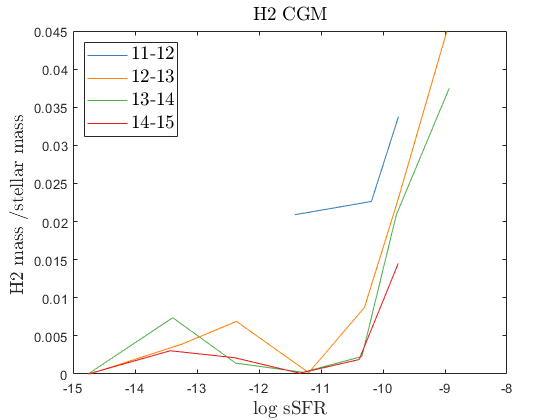


h=[];
figure
for j=1:4
    h(end+1)=plot(hprofs.byHost.xsfrMed(:,j),hprofs.byHost.CGMall.h2MassSFRMedN(1,:,j),...
        'color',colors(cind(j),:),'DisplayName',htag{j});
    if j==1;hold on;end
    % h(end+1)=plot(hprofs.byHost.xAvg(:,j),hprofs.byHost.Gal.hiMassAvgDN(1,:,j),'--',...
    %     'color',colors(cind(j),:),'DisplayName',htag{j});
end

legend(h,'fontsize',14,'location','northwest','interpreter','latex');
xlabelmine('log sSFR');
ylabelmine('H2 mass /stellar mass ');
titlemine('H2 CGM');

## compare to mock observations Gal 

% prepare deficiency data
ms=(galHI_star(1).xMedian);
hm=galHI_star(1).yMedian;
ms=ms(~isnan(ms));
hm=hm(~isnan(ms));
msMass=interp1(ms,hm,log10(hih2Struct.galMass));

hiDef=(hih2Struct.Gal.GalHIMass(1,:)./hih2Struct.galMass)./10.^(msMass)-1;

res= generate_profile_from_vantagePoint_Catalog(satStructY,fofs,subs,'mean200','mass',massThresh,'hiDef',hiDef);



## plot

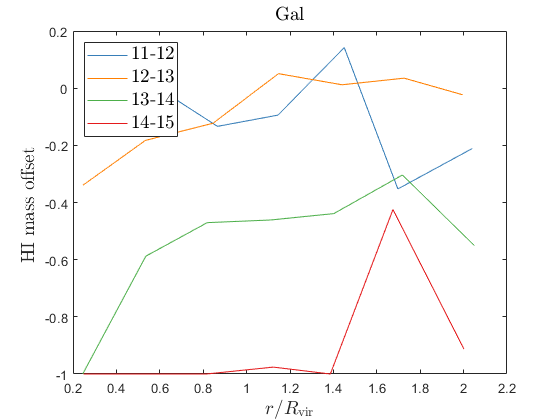




figure
h=[];

for j=1:4
     h(end+1)=plot(hprofs.byHost.xMed(:,j),hprofs.byHost.Gal.hiMassMedDN(1,:,j),...
         'color',colors(cind(j),:),'DisplayName',htag{j});
    if j==1;hold on;end
%    h(end+1)=plot(res.rposMed(:,j),res.hiDefMedMed(3,:),'--',...
%        'color',colors(cind(j),:),'DisplayName',[htag{j} ' Mock']);
    % h(end+1)=plot(hprofs.byHost.xAvg(:,j),hprofs.byHost.Gal.hiMassAvgDN(1,:,j),'--',...
    %     'color',colors(cind(j),:),'DisplayName',htag{j});
end

legend(h,'fontsize',14,'location','northwest','interpreter','latex');
xlabelmine('$r/R_\mathrm{vir}$');
ylabelmine('HI mass offset ');
titlemine('Gal');

## cgpm


figure
h=[];

for j=1:4
    h(end+1)=plot(hprofs.byHost.xMed(:,j),hprofs.byHost.CGMall.hiMassMedDN(1,:,j),...
        'color',colors(cind(j),:),'DisplayName',htag{j});
    if j==1;hold on;end
    % h(end+1)=plot(hprofs.byHost.xAvg(:,j),hprofs.byHost.CGMall.hiMassAvgDN(1,:,j),'--',...
    %     'color',colors(cind(j),:),'DisplayName',htag{j});
    
    % h(end+1)=plot(hprofs.byHost.xMed(:,j),hprofs.byHost.CGMin.hiMassMed(1,:,j),'--',...
    %     'color',colors(cind(j),:),'DisplayName',htag{j});
    %
    % h(end+1)=plot(hprofs.byHost.xMed(:,j),hprofs.byHost.CGMout.hiMassMed(1,:,j),':',...
    %     'color',colors(cind(j),:),'DisplayName',htag{j});
    
    
end
xlabelmine('$r/R_\mathrm{vir}$');
ylabelmine('HI mass offset ');
titlemine('CGM');



## plot by stellar mass

% figure
% h=[];
% 
% for j=1:3
%     h(end+1)=plot(hprofs.byHost.xMed(:,j),hprofs.byMass.Gal.hiMassMed(1,:,j),...
%         'color',colors(cind(j),:),'DisplayName',mtag{j});
%     if j==1;hold on;end
% end
% 
% legend(h,'fontsize',14,'location','northwest','interpreter','latex');
% xlabelmine('$r/R_\mathrm{vir}$');
% ylabelmine('HI mass $[\mathrm{M_\odot}]$');
% titlemine('Gal');
% 
% figure
% h=[];
% 
% for j=1:3
%     h(end+1)=plot(hprofs.byHost.xMed(:,j),hprofs.byMass.CGMall.hiMassMed(1,:,j),...
%         'color',colors(cind(j),:),'DisplayName',mtag{j});
%     if j==1;hold on;end
%     
%     h(end+1)=plot(hprofs.byHost.xMed(:,j),hprofs.byMass.CGMin.hiMassMed(1,:,j),'--',...
%         'color',colors(cind(j),:),'DisplayName',mtag{j});
%     
%     h(end+1)=plot(hprofs.byHost.xMed(:,j),hprofs.byMass.CGMout.hiMassMed(1,:,j),':',...
%         'color',colors(cind(j),:),'DisplayName',mtag{j});
%     
%     
% end
% 
% legend(h(1:3:9),'fontsize',14,'location','northwest','interpreter','latex');
% xlabelmine('$r/R_\mathrm{vir}$');
% ylabelmine('HI mass $[\mathrm{M_\odot}]$');
% titlemine('CGM');
% 
% % normalized
% 
% figure
% h=[];
% 
% for j=1:3
%     h(end+1)=plot(hprofs.byHost.xMed(:,j),hprofs.byMass.Gal.hiMassMedN(1,:,j),...
%         'color',colors(cind(j),:),'DisplayName',mtag{j});
%     if j==1;hold on;end
% end
% 
% legend(h,'fontsize',14,'location','northwest','interpreter','latex');
% xlabelmine('$r/R_\mathrm{vir}$');
% ylabelmine('HI mass / stellaer mass');
% titlemine('Gal');
% 
% figure
% h=[];
% 
% for j=1:3
%     h(end+1)=plot(hprofs.byHost.xMed(:,j),hprofs.byMass.CGMall.hiMassMedN(1,:,j),...
%         'color',colors(cind(j),:),'DisplayName',mtag{j});
%     if j==1;hold on;end
%     
%     h(end+1)=plot(hprofs.byHost.xMed(:,j),hprofs.byMass.CGMin.hiMassMedN(1,:,j),'--',...
%         'color',colors(cind(j),:),'DisplayName',mtag{j});
%     
%     h(end+1)=plot(hprofs.byHost.xMed(:,j),hprofs.byMass.CGMout.hiMassMedN(1,:,j),':',...
%         'color',colors(cind(j),:),'DisplayName',mtag{j});
%     
%     
% end
% 
% legend(h(1:3:9),'fontsize',14,'location','northwest','interpreter','latex');
% xlabelmine('$r/R_\mathrm{vir}$');
% ylabelmine('HI mass / stellaer mass');
% titlemine('CGM');
% 
% 

## plot offset by mass

% 
% figure
% h=[];
% 
% for j=1:3
%     h(end+1)=plot(hprofs.byHost.xMed(:,j),hprofs.byMass.Gal.hiMassMedN(1,:,j),...
%         'color',colors(cind(j),:),'DisplayName',htag{j});
%     if j==1;hold on;end
%     h(end+1)=plot(hprofs.byHost.xAvg(:,j),hprofs.byMass.Gal.hiMassAvgD(1,:,j),'--',...
%         'color',colors(cind(j),:),'DisplayName',htag{j});
% end
% 
% legend(h,'fontsize',14,'location','northwest','interpreter','latex');
% xlabelmine('$r/R_\mathrm{vir}$');
% ylabelmine('HI mass offset ');
% titlemine('Gal');
% 
% figure
% h=[];
% 
% for j=1:3
%     h(end+1)=plot(hprofs.byHost.xMed(:,j),hprofs.byMass.CGMall.hiMassMedDN(1,:,j),...
%         'color',colors(cind(j),:),'DisplayName',htag{j});
%     if j==1;hold on;end
%     h(end+1)=plot(hprofs.byHost.xAvg(:,j),hprofs.byMass.CGMall.hiMassAvgDN(1,:,j),'--',...
%         'color',colors(cind(j),:),'DisplayName',htag{j});
%     
%     % h(end+1)=plot(hprofs.byHost.xMed(:,j),hprofs.byHost.CGMin.hiMassMed(1,:,j),'--',...
%     %     'color',colors(cind(j),:),'DisplayName',htag{j});
%     %
%     % h(end+1)=plot(hprofs.byHost.xMed(:,j),hprofs.byHost.CGMout.hiMassMed(1,:,j),':',...
%     %     'color',colors(cind(j),:),'DisplayName',htag{j});
%     
%     
% end
% xlabelmine('$r/R_\mathrm{vir}$');
% ylabelmine('HI mass offset ');
% titlemine('CGM');